Estimate DOA

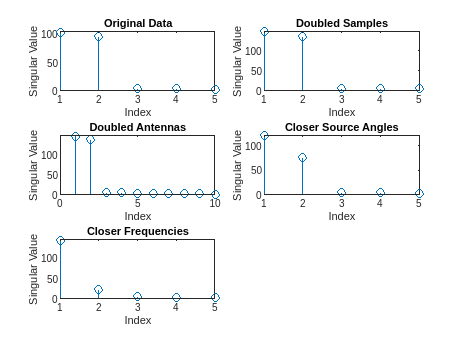

% Test parameters
M = 5; % Number of antennas
N = 20; % Number of samples
theta = [-20 * (pi/180); 30 * (pi/180)]; % Directions of arrival in radians
f = [0.1; 0.3]; % Normalized frequencies
SNR = [20; 20]; % Signal-to-noise ratios in dB

% Generate data and perform SVD for original data
[X, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular] = svd(X);

% Double samples
N = 40;
[X_sample, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular_sample] = svd(X_sample);

% Double antennas
M = 10; N = 20;
[X_ant, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular_ant] = svd(X_ant);

% Make source angles closer
M = 5; theta = [-5 * (pi/180); 10 * (pi/180)];
[X_angle, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular_angle] = svd(X_angle);

% Make frequencies closer
theta = [-20 * (pi/180); 30 * (pi/180)]; f = [0.29; 0.3];
[X_freq, ~, ~] = gen_data(M, N, 0.5, theta, f, SNR);
[~, Singular_freq] = svd(X_freq);

% Store singular values and titles in arrays
singular_values = {diag(Singular), diag(Singular_sample), diag(Singular_ant), diag(Singular_angle), diag(Singular_freq)};
titles = ["Original Data", "Doubled Samples", "Doubled Antennas", "Closer Source Angles", "Closer Frequencies"];

% Create a figure and plot all the singular values in subplots
figure;
num_plots = length(singular_values);
for i = 1:num_plots
    subplot(ceil(num_plots/2), 2, i); % Arrange subplots in a grid
    stem(singular_values{i});
    title(titles(i));
    xlabel('Index');
    ylabel('Singular Value');
end

Estimating Frequencies

% 
% Parameters
M = 5; % Number of antennas
N = 20; % Number of samples
theta = [-20 * (pi/180); 30 * (pi/180)]; % Directions of arrival in radians
f = [0.1; 0.5]; % Normalized frequencies
SNR = [10; 20]; % Signal-to-noise ratios in dB
delta = 0.5;

% Generate data
[X, ~, ~] = gen_data(M, N, delta, theta, f, SNR);

% Perform ESPRIT
freq = abs(espritfreq(X, 2));

% Display results
disp('Estimated Frequencies:');

Estimated Frequencies:


disp(freq);

    0.4998
    0.0999



Jointly estimating DOA and Frequency

clear all;
% Parameters
M = 5; % Number of antennas
N = 20; % Number of samples
theta = [-20 * (pi/180); 30 * (pi/180)]; % Directions of arrival in radians
f = [0.1; 0.5]; % Normalized frequencies
SNR = [20; 20]; % Signal-to-noise ratios in dB
delta = 0.5;
d=2;

% Generate data
[X, ~, ~] = gen_data(M, N, delta, theta, f, SNR);



[theta_joint,f_joint]=joint(X,d,M);

Functions

function [X,A,S] = gen_data(M,N,delta,theta,f,SNR)
    % Initialize matrices
    num_sources=length(theta);
    X = zeros(M, N);
    A = zeros(M, num_sources);
    S = zeros(length(theta), N);
    Noise=zeros(M,N);
    
    % Generate the signals and array responses
    for d = 1:num_sources
        %calculate signal amplitude
        SNR_linear = 10.^(SNR(d) / 10);
        amplitude =sqrt(SNR_linear);
        for n = 1:N
            % Generate signal
            S(d, n) = amplitude*exp(1i * 2 * pi * f(d) * n);
        end
        for m = 1:M
            % Calculate array response
            A(m, d) = exp((m-1)*1i * 2 * pi * delta * sin(theta(d)));
        end
    end

    % Generate noise with consistent dimensions
    real_noise = randn(size(X));
    imag_noise = randn(size(X));
    % Combine real and imaginary parts to form complex noise
    noise = real_noise + 1i * imag_noise;
    % Calculate the power of the generated noise
    noise_power = mean(abs(noise(:)).^2);
    % Normalize the noise to have power 1
    normalized_noise = noise / sqrt(noise_power);

    Noise= normalized_noise;

    %caculate the M by N matrix X
    X=A*S;
    X = X + Noise;
end


function theta = esprit(X,d)
    M=size(X,1);

    %let us group first M-1 and last M-1 data records
    X_1=X(1:M-1,:);
    Y=X(2:M,:);

    Z=[X_1;Y];
    [U_z,~,~]=svd(Z);
    U_z_hat=U_z(:,1:d);
    U_x_hat=U_z_hat(1:M-1,:);
    U_y_hat=U_z_hat(M:end,:);

    %temp=(ctranspose(U_x_hat)*U_x_hat)*ctranspose(U_x_hat)*U_y_hat;
    temp=pinv(U_x_hat)*U_y_hat;
    [T,theta]=eig(temp);
    theta=diag(theta);
end

function freqs = espritfreq(X, d)

    % Singular value decomposition
    [U, ~, V] = svd(X, 'econ');
    V1 = V(1:end-1, 1:d);
    V2 = V(2:end, 1:d);
    D = eig(pinv(V1) * V2);
    % Frequency estimation
    freqs = angle(D)  / (2 * pi);
end

function [theta,f] = joint(X,d,m)
    %lets create a m-smoothed X_m matrix
    N=size(X,2);
    M=size(X,1);
    Xm=zeros([m*M,N-m+1]);
    for i=1:m
        Xm((i-1)*M+1:i*M,: )=X(:,i:N-m+i);
    end

    %now lets take the SVD of Xm
    [Um,~,~]=svd(Xm);
    Um=Um(:,1:d);

    Um_phix=Um(1:M*(m-1),:);
    Um_phiy=Um(M+1:M*m,:);
    My=pinv(Um_phix)*Um_phiy;

    Um_theta_x=[];
    Um_theta_y=[];

    for i=1:m-1
        Um_theta_x=vertcat(Um_theta_x,Um(i*(M)+1:(i+1)*M-1,:));
        Um_theta_y=vertcat(Um_theta_y,Um(i*(M)+2:(i+1)*M,:));
    end
    Mz=pinv(Um_theta_x)*Um_theta_y;
    M=[My,Mz];
    [V,D]=joint_diag(M,1.0e-8);
    [~,v]=size(D);
    Phi=D(:,1:v/2);
    Theta=D(:,v/2+1:v);
    f=angle(eig(Phi))/(2*pi);
    theta=rad2deg( asin(angle(eig(Theta))/pi));

end


